## Feature Manipulation Experiment 2 

**In this notebook we will analyze the features from instances obtained in "Exp3_RHHjustification" and come up with a SHH model able to select the best solver among them. **

**Files are needed: "Exp3_I1.mat", "Exp3_I2.mat", "Exp3_I3.mat", 'Results_Exp3_RHHjustification.mat' and 'MPA.mat'**

 **Let's prepare everything and load all we need: **

will try to design by hand a HH able to properly solve such instances. 

%First let's clean everything and add needed folders
clc
clear
close all

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities


**Loading instances from Exp3_RHHjustification:**

load("Exp3_I1.mat")
load("Exp3_I2.mat")
load("Exp3_I3.mat")

%For precaution let's reset the instances 
I1.reset
I2.reset
I3.reset

**Now let's load the results from Exp3_RHHjustification to remember the nature of the instances: **

load('Results_Exp3_RHHjustification.mat')
Results

Results = 5×4 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}
    {["HHExp2"]}    {[          42]}    {[     21.0665]}    {[     68.7435]}


**It looks like LPT, SPT and MPA solve better I1,I2 and I3 respectively. Let's now look at the features. **

I1.getFeatureVector([1 2 3 4 5])

ans =     0.2812    0.4380    0.5413    0.6667    0.2500


I2.getFeatureVector([1 2 3 4 5])

ans =     0.0749    0.1805    0.1765    0.4074    0.1250


I3.getFeatureVector([1 2 3 4 5])

ans =     0.0751    0.0615    0.3064    0.4074    0.1250


**The HHExp2 was created with a training method, let's create a model for I1 and I2 by looking at the features of the instances: **

%let's call it FM_HH_Exp2
fields=struct('nbRules',2,'selectedSolvers',[1 2],'selectedFeatures',[1]);
FM_HH_Exp2=ruleBasedSelectionHH(fields);

Model1=[0.1 2; 0.2 1];
FM_HH_Exp2.value=Model1;

InstanceSet={I1 I2 I3}; 
solvedInstanceSet_HH=FM_HH_Exp2.solveInstanceSet(InstanceSet);

Results{5,1}='HH_1';
Results{5,2}=solvedInstanceSet_HH{1}.solution.makespan;
Results{5,3}=solvedInstanceSet_HH{2}.solution.makespan;
Results{5,4}=solvedInstanceSet_HH{3}.solution.makespan;
Results

Results = 5×4 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}
    {'HH'      }    {[          42]}    {[     21.0665]}    {[     73.0239]}


**It worked, our created HH solves the I1 similar to LPT, I2 similar to SPT, and is being outperformed by MPA when solving I3.**

**Now we will create a SHH model having MPA and the previous HH as solvers. **

%let's load MPA 
load('MPA.mat')

**In order to make the SHH to work (for now), we need to convert MPA and the HH to a multiHH class: **

%First the HH
props = struct('nbLayers',1,'nbRules',2, 'selectedSolvers',1:2, 'selectedFeatures', [1]); %parameters for the HH in the multi form containing LPT and SPT and the first feature
HH_multi=ruleBasedSelectionHHMulti(props); %Creating the HH with multiHH class

HH_multi.value = FM_HH_Exp2.value; %copying the model of the HH

%Now MPA
props = struct('nbLayers',1,'nbRules',1, 'selectedSolvers',3, 'selectedFeatures', [1]); %parameters for MPA in the multi form
MPA_multi=ruleBasedSelectionHHMulti(props); %creating MPA with multiHH class

%Creating the SHH model 

props = struct('nbLayers',2,'selectedSolvers',1:2,...
                 'nbRules',2,'innerHHs',[HH_multi MPA_multi],'selectedFeatures', [1]);
FM_Exp2_SHH=ruleBasedSelectionHHMulti(props)

FM_Exp2_SHH = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>

**The next step is to determine what feature we want to use and how many rules are necessary. **

**Looking at the initial features of the three instances we want to solve, the feature 2 is different for the three instances **

**(0.4380, 0.1805, and 0.0615, respectively) . Ultimately we want the HH to solve the first two instances and MPA to solve the third one. Let's try a couple of rules based on the second feature. **

props = struct('nbLayers',2,'selectedSolvers',1:2,...
                 'nbRules',2,'innerHHs',[HH_multi MPA_multi],'selectedFeatures', [2]); %creating model with feature 2
FM_Exp2_SHH=ruleBasedSelectionHHMulti(props);

Model2=[0.3 1; 0.1 2]; %creating the SHH model: 0.2 is closer to the feature 2 of instances 1 and 2, and 0 is closer to the feature 2 of instance 3. 
FM_Exp2_SHH.value=Model2 %assigning the model to the SHH

FM_Exp2_SHH = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>

**Now let's test our model by solving the three instances:**


solvedInstanceSet_SHH=FM_Exp2_SHH.solveInstanceSet(InstanceSet);
Results{6,1}='SHH';
Results{6,2}=solvedInstanceSet_SHH{1}.solution.makespan;
Results{6,3}=solvedInstanceSet_SHH{2}.solution.makespan;
Results{6,4}=solvedInstanceSet_SHH{3}.solution.makespan;
Results

Results = 6×4 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}
    {'HH'      }    {[          42]}    {[     21.0665]}    {[     73.0239]}
    {'SHH'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}


**It looks like this feature is not producing the result that we expected, the SHH is having a similar performance as the HH. One explanation is that the initial feature 2 of the instance 3 is only temporary and when the instance schedule progresses the feature value rises similar to the instances 1 and 2. Let's try another configuration. **

%VISUALIZATION METHODS

%MPA_multi.solveInstanceSet(InstanceSet);
%FM_Exp2_SHH.plotSolverUsageDistributionMulti(3,true) %method to see what
%solvers were used 

%MPA_multi.plotSolverUsageDistributionMulti(3,true)
%FM_Exp2_SHH.plotSolverUsage(3) %method to visualize what solver what used
%in what step
%MPA_multi.plotSolverUsage(3)

%FM_Exp2_SHH.plotSolutionEvolution(3) %method to visualize how the makespan
%is changing in every step 

%MPA_multi.plotSolutionEvolution(3)


**Let's use the feature number 3, instances have initial feature 3: 0.5413, 0.1765, and 0.3064, respectively. So it looks we can't use only two rules because the instance 3 has a value of feature 3 in between of those of instances 1 and 2. Let's create a model with 3 rules: **

props = struct('nbLayers',2,'selectedSolvers',1:2,...
                 'nbRules',2,'innerHHs',[HH_multi MPA_multi],'selectedFeatures', [3]);
FM_Exp2_SHH=ruleBasedSelectionHHMulti(props);

Model2=[0.5 1; 0.35 1;0.41 2;]; %Using three rules 
FM_Exp2_SHH.value=Model2; %assigning the model to the SHH

%solving the instances
solvedInstanceSet_SHH=FM_Exp2_SHH.solveInstanceSet(InstanceSet);
Results{6,1}='SHH';
Results{6,2}=solvedInstanceSet_SHH{1}.solution.makespan;
Results{6,3}=solvedInstanceSet_SHH{2}.solution.makespan;
Results{6,4}=solvedInstanceSet_SHH{3}.solution.makespan;
Results

Results = 6×4 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}
    {'HH'      }    {[          42]}    {[     21.0665]}    {[     73.0239]}
    {'SHH'     }    {[          42]}    {[     21.0665]}    {[     43.0250]}


**It looks like we got a lot closer with three rules! When solving the third instance the result is not as good as MPA, but is definitely better than the HH. Let's see if adding another rule we can improve this result. **

**Adding a fourth rule to the previous model: **

Model2=[0.5 1; 0.35 1;0.41 2; 0.3 2]; %Using four rules 
FM_Exp2_SHH.value=Model2; %assigning the model to the SHH

%solving the instances
solvedInstanceSet_SHH=FM_Exp2_SHH.solveInstanceSet(InstanceSet);
Results{6,1}='SHH';
Results{6,2}=solvedInstanceSet_SHH{1}.solution.makespan;
Results{6,3}=solvedInstanceSet_SHH{2}.solution.makespan;
Results{6,4}=solvedInstanceSet_SHH{3}.solution.makespan;
Results

Results = 6×4 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}
    {'HH'      }    {[          42]}    {[     21.0665]}    {[     73.0239]}
    {'SHH'     }    {[          42]}    {[     21.0665]}    {[     33.0303]}


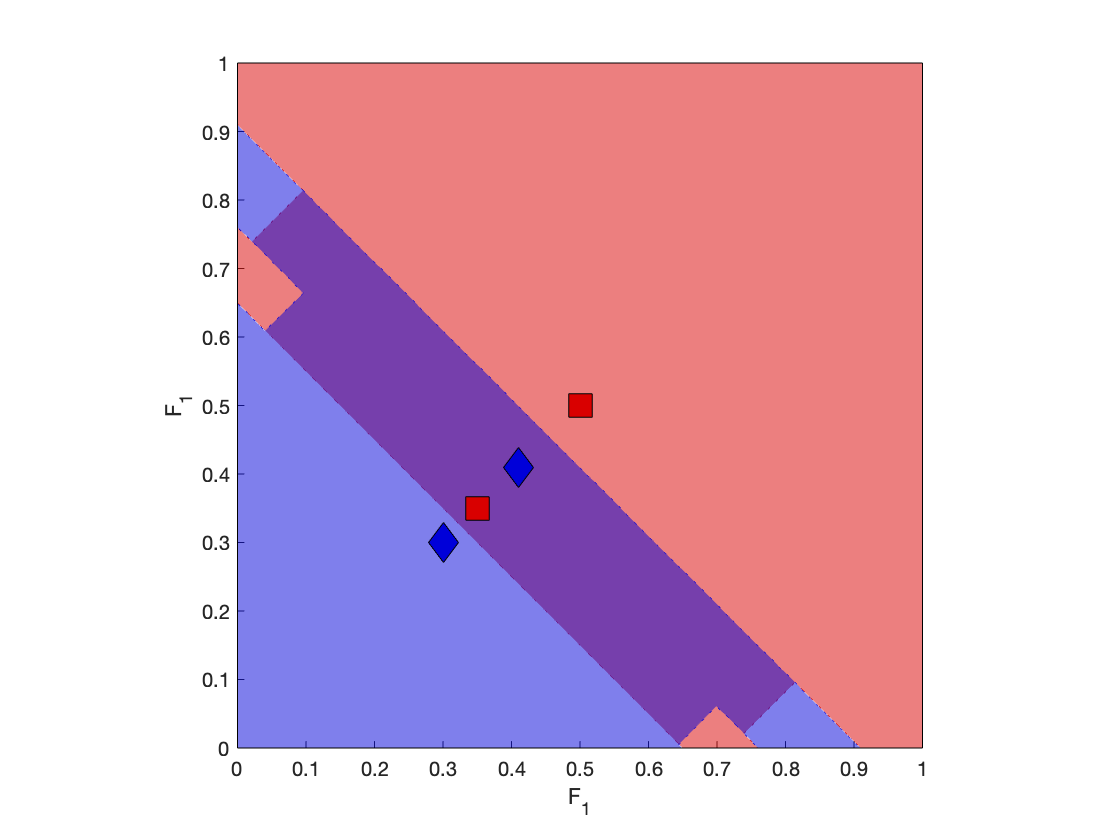

ans =     0.7712    0.4021


%Visualizing the feature space
FM_Exp2_SHH.plotZones(0:0.001:1,1,[1 1],1)

**Adding a fifth rule**

Model2=[0.5 1; 0.35 1;0.41 2; 0.3 2; 0.57 2]; %Using five rules 
FM_Exp2_SHH.value=Model2; %assigning the model to the SHH

%solving the instances
solvedInstanceSet_SHH=FM_Exp2_SHH.solveInstanceSet(InstanceSet);
Results{6,1}='SHH';
Results{6,2}=solvedInstanceSet_SHH{1}.solution.makespan;
Results{6,3}=solvedInstanceSet_SHH{2}.solution.makespan;
Results{6,4}=solvedInstanceSet_SHH{3}.solution.makespan;
Results

Results = 6×4 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}
    {'HH'      }    {[          42]}    {[     21.0665]}    {[     73.0239]}
    {'SHH'     }    {[          42]}    {[     21.0665]}    {[     33.0303]}


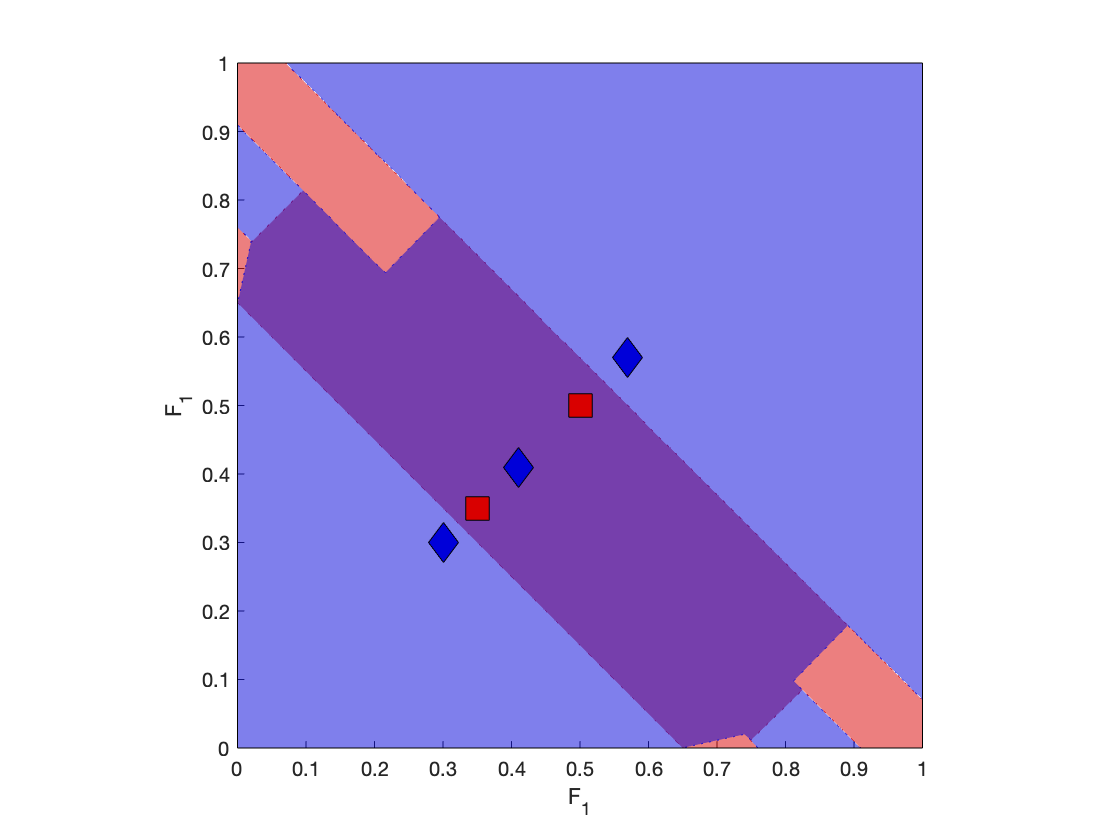

ans =     0.3403    0.9392



%Visualizing the feature space
FM_Exp2_SHH.plotZones(0:0.001:1,1,[1 1],1)




%More visualization methods


%FM_Exp2_SHH.plotSolverUsage(3)
%FM_Exp2_SHH.plotSolverUsageDistributionMulti(3,true)

%FM_Exp2_SHH.plotFeatureMap(InstanceSet,"full",struct('features',[1 1]),true,3)
%MPA_multi.plotFeatureMap(InstanceSet,"full",struct('features',[1 1]),true,3)

**It looks like we did it! This time the SHH found the best performances combining its solvers. Having a Squared Hyper-heuristic with solvers of different level (or deep) we created what we define as a "Flexible Squared Hyper-Heuristic". **

**Let's save all solvers for future experiments**

save('FM_Exp2_SHH','FM_Exp2_SHH')
save('FM_Exp2_HH','FM_HH_Exp2')
save('FM_Exp2_HH_multi','HH_multi')
save('MPA_multi','MPA_multi')
save('FM_Exp2_Results','Results')